## 2. 直線上の流れ（p18）

### 命題


$$\frac{\mathrm{dx}}{\mathrm{dt}}=\mathrm{sin}\left(x\right)$$


#### 解析的な解


$$\begin{array}{l}
\int \frac{1}{\;\mathrm{sin}\left(x\right)}\mathrm{dx}=\int \mathrm{dt}\\
t=\mathrm{ln}\;\left|\;\mathrm{tan}\left(\frac{x}{\;2}\right)\right|+C=-\mathrm{ln}\;\left|\frac{1-\mathrm{cos}\left(x\right)\;}{\mathrm{sin}\left(x\right)}\right|+C=-\mathrm{ln}\;\left|\mathrm{csc}\left(x\right)+\mathrm{cot}\left(x\right)\right|+C
\end{array}$$


$t=0$で$x=x_0$のとき、


$$C=\mathrm{ln}\;\left|\frac{\;1-\mathrm{cos}\left(x_0 \right)}{\mathrm{sin}\left(x_{o\;} \right)}\right|$$


### ODEソルバーによる解

参考：[https://jp.mathworks.com/help/matlab/math/choose-an-ode-solver.html](https://jp.mathworks.com/help/matlab/math/choose-an-ode-solver.html)

### 特定の初期条件に対するプロット

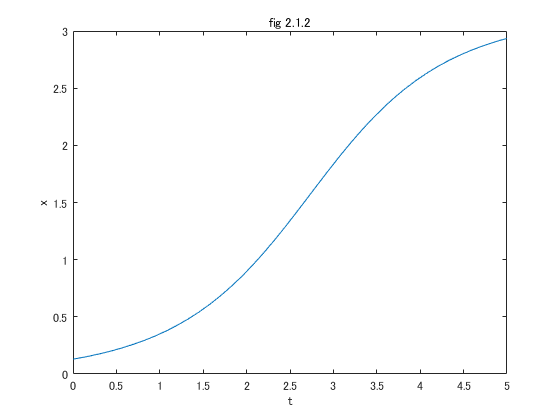

tspan = [0 5];
x0 =0.13;
[t,x] = ode45(@myODE, tspan, x0);

plot(t,x);
title("fig 2.1.2");
xlabel("t");
ylabel("x");

### 様々な初期条件をまとめてプロット

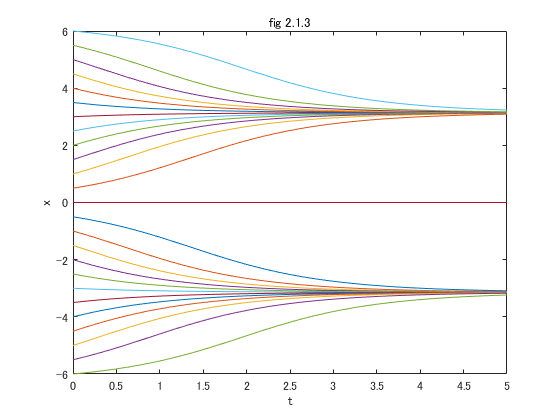

tspan = [0 5];
x0list = [0:0.5:2*pi 0:-0.5:-2*pi];
for x0 = x0list
    [t,x] = ode45(@myODE, tspan, x0);
    plot(t,x);
    hold on
end
hold off
title("fig 2.1.3")
xlabel("t");
ylabel("x");